# Task 3 - Number plate recognition

## Pre-processing

### Read images and turn them to grayscale

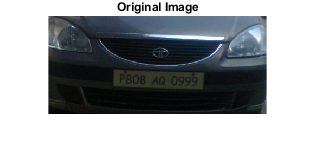

img_path = "images/final/task_3/";

image1 = imread(img_path + "example_number_plate.png");
imshow(image1); title("Original Image");

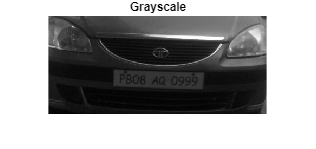


img1gray = rgb2gray(image1);
imshow(img1gray); title("Grayscale");

### Noise removal

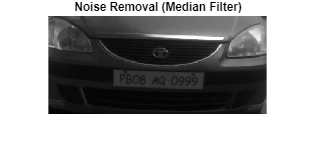

% Here I guess we could use imbilatfilt to filter it 
% bilaterally like in the documentation.
img1med = medfilt2(img1gray);
imshow(img1med); title("Noise Removal (Median Filter)");

### Contrast Enhancement 

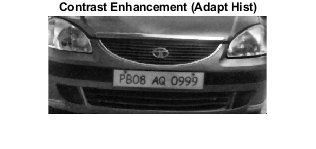

img1cont = adapthisteq(img1med);
imshow(img1cont); title("Contrast Enhancement (Adapt Hist)");

## Morphological Opening and Image Subtraction Operations

### Opening with 'disk'

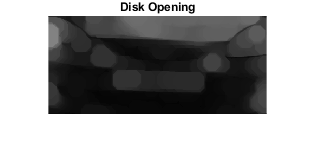

se = strel('disk',15);
img1open = imopen(img1cont,se);
imshow(img1open); title("Disk Opening");

### Subtraction from enhanced image

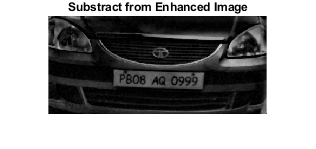

img1sub = imsubtract(img1cont, img1open);
imshow(img1sub); title("Substract from Enhanced Image");

## Image binarization

% Find grayscale threshold and binarize
bins = 11;
[counts,x] = imhist(img1sub, bins);
g_thresh = otsuthresh(counts) %graythresh(img1sub)

g_thresh = 0.2000

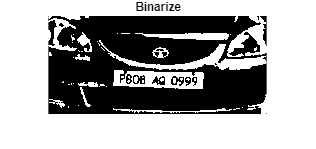


img1bin = imbinarize(img1sub, g_thresh);

imshow(img1bin); title("Binarize");

## Detect edges with the Sobel operator

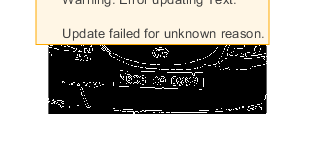

img1edge = edge(img1bin);
imshow(img1edge); title("Sobel Edge Detection");

## Candidate plate area detection with morphological operators

### Dilation

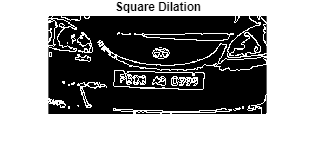

se2 = strel('square', 2);
img1dil = imdilate(img1edge, se2);
imshow(img1dil); title("Square Dilation");

### Filling holes

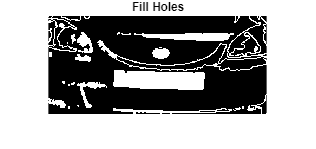

img1fill = imfill(img1dil, 'holes');
imshow(img1fill); title("Fill Holes");

### Opening

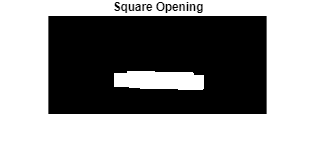

se3 = strel('square',22);
img1open = imopen(img1fill, se3);
imshow(img1open); title("Square Opening");

### Erosion

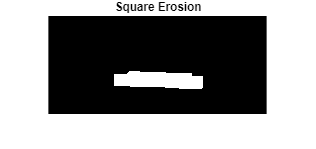

% This does not seem necessary.
se4 = strel('square', 4);
img1erode = imerode(img1open,se4);
imshow(img1erode); title("Square Erosion");

### Apply Mask

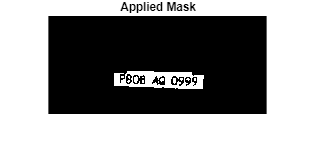

img1bin(~img1open) = 0;
imshow(img1bin); title("Applied Mask");

## OCR

Should make it only check for 

- Letters (Language) for the first 4 letters

- Letters for the middle 2 letters

- Numeric digits for the last 4 digits

% Crop region of text if needed
%crop_rec = [0.5 0.5 x y];

% Resize image (bigger) to make it easier for OCR
%img1bin_resized = imresize(img1bin, 3);
%imshow(img1bin_resized); title("Resized for OCR");

By default the ocr function will return a separate word for each set of letters that are separated by some space.

ocr_words_letters = ocr(img1bin, 'CharacterSet', 'A':'Z');
first_4_letters = ocr_words_letters.Words{1};
middle_2_letters = ocr_words_letters.Words{2};

ocr_words_digits = ocr(img1bin, 'CharacterSet', '0123456789');
last_4_digits = ocr_words_digits.Words{3};

disp(first_4_letters + " " + middle_2_letters + " " + last_4_digits);

BOG AG 0999



fclose('all');